# simulation of a two-qubit gate using a resonator as coupler

similar example with qutip  can also be found [here](http://nbviewer.jupyter.org/github/jrjohansson/qutip-lectures/blob/master/Lecture-2A-Cavity-Qubit-Gates.ipynb). 

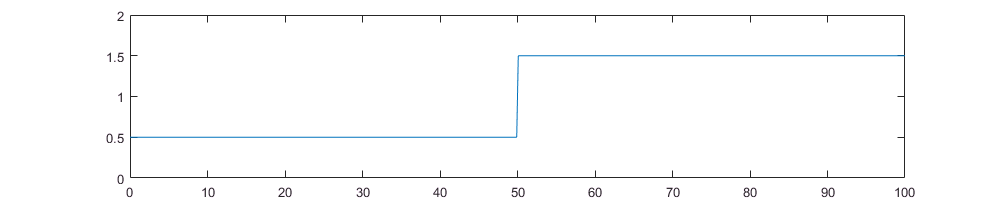

tic;

N=10;
wc = 5.0*2*pi;
w1 = 3.0*2*pi;
w2 = 2.0*2*pi;

g1 = 0.01*2*pi;
g2 = 0.0125*2*pi;

tlist = linspace(0,100,500);

width = 0.5;
T01 = 20; T02 = 60; 
Tgate1 = (1*pi)/(4*g1);
Tgate2 = (2*pi)/(4*g2);

% operators:
a = tensor(destroy(N),qeye(2),qeye(2));
n = (a'*a);

sm1 = tensor(qeye(N),destroy(2),qeye(2));
sz1 = tensor(qeye(N),sigmaz(),qeye(2));
n1 = (sm1'*sm1);

sm2 = tensor(qeye(N),qeye(2),destroy(2));
sz2 = tensor(qeye(N),qeye(2),sigmaz());
n2 = (sm2'*sm2);

Hc = (a'*a);
H1 = -0.5*sz1;
H2 = -0.5*sz2;
Hc1 = g1*(a'*sm1 + a*sm1');
Hc2 = g2*(a'*sm2 + a*sm2');

H = wc*Hc + w1*H1 + w2*H2 + Hc1 + Hc2;
psi0 = tensor(fock(N,0),basis(1),basis(0));

step_t = @(w1,w2,t0,width,t) w1+(w2-w1)*(t>t0); 
figure('Position',[100,100,1000,200])
axis tight;
plot(tlist,step_t(0.5,1.5,50,0,tlist)); 
ylim([0,2]); 

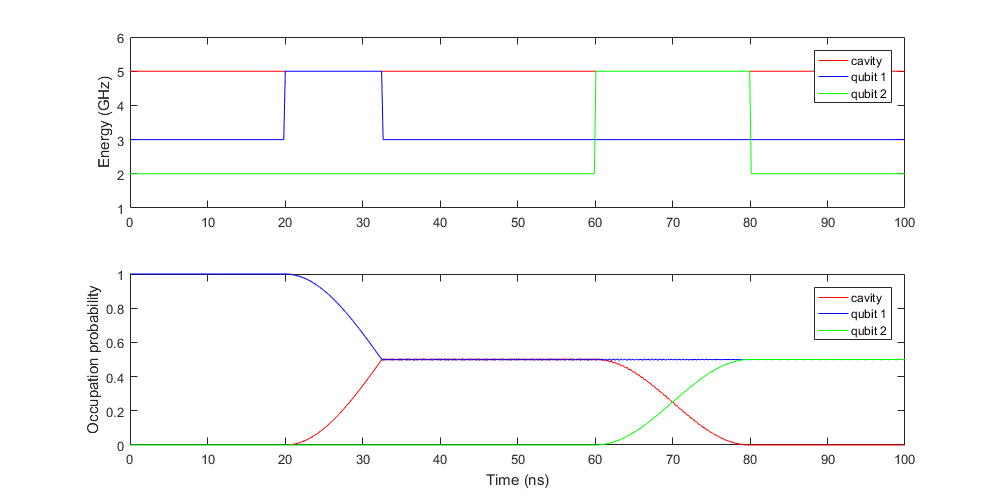


wc_t = @(t) wc+0*t;
w1_t = @(t) w1 + step_t(0, wc-w1, T01, width,t) - step_t(0, wc-w1, T01+Tgate1, width,t);
w2_t = @(t) w2 + step_t(0, wc-w2, T02, width,t) - step_t(0, wc-w2, T02+Tgate2, width,t);

tH_list = {wc_t,w1_t,w2_t;Hc, H1, H2};
H0 = Hc1 + Hc2;

results = mesolve(H0, tH_list, tlist,psi0,{},{});
figure('Position',[100,100,1000,500])
subplot(2,1,1);axis tight
plot(tlist,wc_t(tlist)/(2*pi),'r-');hold on;
plot(tlist,w1_t(tlist)/(2*pi),'b-');
plot(tlist,w2_t(tlist)/(2*pi),'g-');hold off;
legend('cavity','qubit 1','qubit 2');
ylabel('Energy (GHz)');
ylim([1,6]);

subplot(2,1,2);axis tight
plot(tlist,expect(n,results.state),'r');hold on;
plot(tlist,expect(n1,results.state),'b');
plot(tlist,expect(n2,results.state),'g');hold off;
legend('cavity','qubit 1','qubit 2');
xlabel('Time (ns)');
ylabel('Occupation probability');
ylim([0,1])

%% check the final two-qubit state:
rho_final = results.state{end};
rho_qubits = (ptrace(rho_final,1,[N,2,2]));
rho_qubits_ideal = state2dm((tensor(phasegate(0), phasegate(pi/2))*sqrtiswap()*tensor(basis(1), basis(0))));

fidelity = cal_fidelity(rho_qubits,rho_qubits_ideal)

fidelity = 0.9896

conc = concurrence(rho_qubits)

conc = 0.9914

## Dispersive two-qubit iSWAP gate:

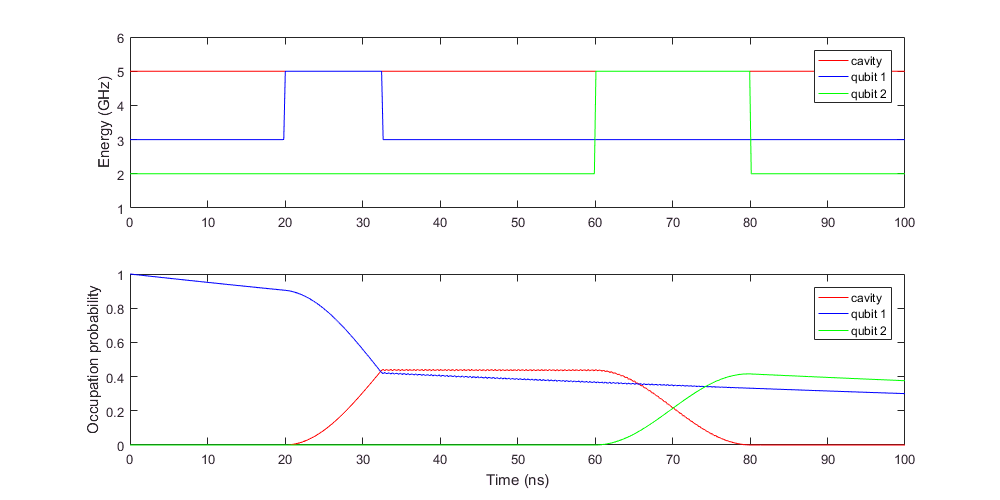

kappa = 0.0001;
gamma1 = 0.005;
gamma2 = 0.005;

cops = {sqrt(kappa)*a, sqrt(gamma1)*sm1, sqrt(gamma2)*sm2};
results = mesolve(H0, tH_list, tlist,psi0,cops,{});

figure('Position',[100,100,1000,500])
subplot(2,1,1);axis tight
plot(tlist,wc_t(tlist)/(2*pi),'r-');hold on;
plot(tlist,w1_t(tlist)/(2*pi),'b-');
plot(tlist,w2_t(tlist)/(2*pi),'g-');hold off;
legend('cavity','qubit 1','qubit 2');
ylabel('Energy (GHz)');
ylim([1,6]);

subplot(2,1,2);axis tight
plot(tlist,expect(n,results.state),'r');hold on;
plot(tlist,expect(n1,results.state),'b');
plot(tlist,expect(n2,results.state),'g');hold off;
legend('cavity','qubit 1','qubit 2');
xlabel('Time (ns)');
ylabel('Occupation probability');
ylim([0,1])


rho_final = results.state{end};
rho_qubits = (ptrace(rho_final,1,[N,2,2]));
fidelity = cal_fidelity(rho_qubits,rho_qubits_ideal)

fidelity = 0.6660

conc = concurrence(rho_qubits)

conc = 0.6663

## two-qubit iSWAP gate: finite pulse rise time

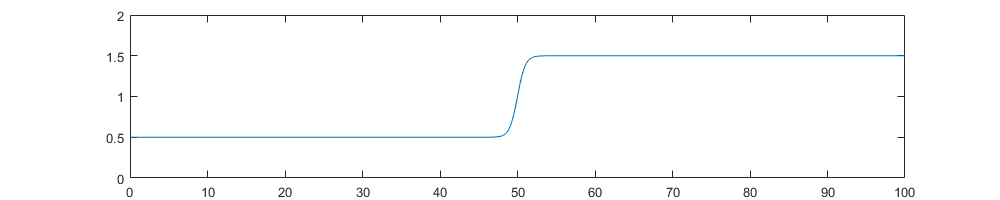

step_t = @(w1,w2,t0,width,t) w1+(w2-w1)./(1+exp(-(t-t0)/width));

figure('Position',[100,100,1000,200])
axis tight;
plot(tlist,step_t(0.5,1.5,50,width,tlist)); 
ylim([0,2]); 

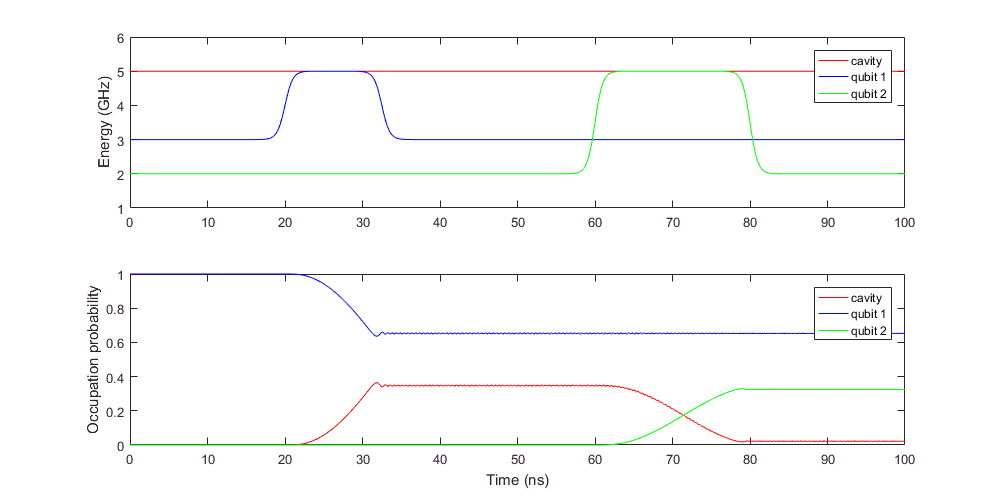

wc_t = @(t) wc+0*t;
w1_t = @(t) w1 + step_t(0, wc-w1, T01, width,t) - step_t(0, wc-w1, T01+Tgate1, width,t);
w2_t = @(t) w2 + step_t(0, wc-w2, T02, width,t) - step_t(0, wc-w2, T02+Tgate2, width,t);

tH_list = {wc_t,w1_t,w2_t;Hc, H1, H2};
H0 = Hc1 + Hc2;

results = mesolve(H0, tH_list, tlist,psi0,{},{});

figure('Position',[100,100,1000,500])
subplot(2,1,1);axis tight
plot(tlist,wc_t(tlist)/(2*pi),'r-');hold on;
plot(tlist,w1_t(tlist)/(2*pi),'b-');
plot(tlist,w2_t(tlist)/(2*pi),'g-');hold off;
legend('cavity','qubit 1','qubit 2');
ylabel('Energy (GHz)');
ylim([1,6]);

subplot(2,1,2);axis tight
plot(tlist,expect(n,results.state),'r');hold on;
plot(tlist,expect(n1,results.state),'b');
plot(tlist,expect(n2,results.state),'g');hold off;
legend('cavity','qubit 1','qubit 2');
xlabel('Time (ns)');
ylabel('Occupation probability');
ylim([0,1])


rho_final = results.state{end};
rho_qubits = (ptrace(rho_final,1,[N,2,2]));
fidelity = cal_fidelity(rho_qubits,rho_qubits_ideal)

fidelity = 0.9343

conc = concurrence(rho_qubits)

conc = 0.9132

## two-qubit iSWAP gate: finite pulse rise time with overshoot

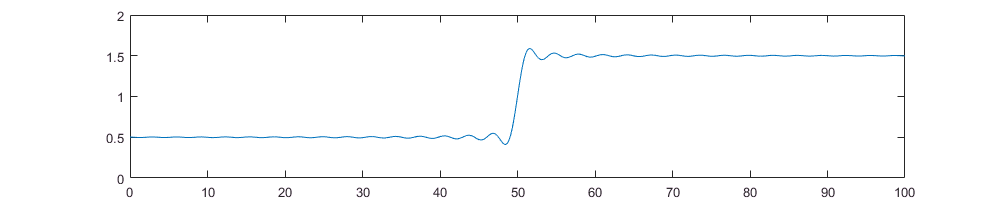

step_t = @(w1,w2,t0,width,t) w1+(w2-w1)*(0.5+sinint((t-t0)/width)/pi);

figure('Position',[100,100,1000,200])
axis tight;
plot(tlist,step_t(0.5,1.5,50,width,tlist)); 
ylim([0,2]); 

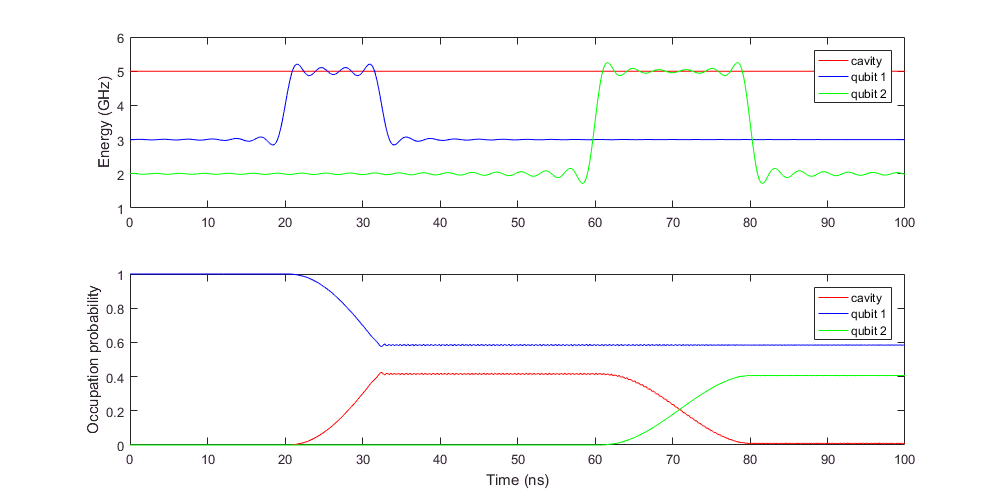

wc_t = @(t) wc+0*t;
w1_t = @(t) w1 + step_t(0, wc-w1, T01, width,t) - step_t(0, wc-w1, T01+Tgate1, width,t);
w2_t = @(t) w2 + step_t(0, wc-w2, T02, width,t) - step_t(0, wc-w2, T02+Tgate2, width,t);

tH_list = {wc_t,w1_t,w2_t;Hc, H1, H2};
H0 = Hc1 + Hc2;

results = mesolve(H0, tH_list, tlist,psi0,{},{});

figure('Position',[100,100,1000,500])
subplot(2,1,1);axis tight
plot(tlist,wc_t(tlist)/(2*pi),'r-');hold on;
plot(tlist,w1_t(tlist)/(2*pi),'b-');
plot(tlist,w2_t(tlist)/(2*pi),'g-');hold off;
legend('cavity','qubit 1','qubit 2');
ylabel('Energy (GHz)');
ylim([1,6]);

subplot(2,1,2);axis tight
plot(tlist,expect(n,results.state),'r');hold on;
plot(tlist,expect(n1,results.state),'b');
plot(tlist,expect(n2,results.state),'g');hold off;
legend('cavity','qubit 1','qubit 2');
xlabel('Time (ns)');
ylabel('Occupation probability');
ylim([0,1])


rho_final = results.state{end};
rho_qubits = (ptrace(rho_final,1,[N,2,2]));
fidelity = cal_fidelity(rho_qubits,rho_qubits_ideal)

fidelity = 0.9658

conc = concurrence(rho_qubits)

conc = 0.9657